%% System definition
A = [-5 2.7;-3.1 1.5];
B = [4 2.1 ; 1.1 3];
C = [1 1];
D = [0 0];

T_s = 0.5;
Ad_euler = eye(size(A))+T_s*A;
Bd_euler = T_s*B;
Cd = C;
Dd = D;

%% SS model creation
sys_cont  = ss(A,B,C,D)


sys_cont =
 
  A = 
         x1    x2
   x1    -5   2.7
   x2  -3.1   1.5
 
  B = 
        u1   u2
   x1    4  2.1
   x2  1.1    3
 
  C = 
       x1  x2
   y1   1   1
 
  D = 
       u1  u2
   y1   0   0
 
Continuous-time state-space model.


sys_euler = ss(Ad_euler,Bd_euler,Cd,Dd,T_s)


sys_euler =
 
  A = 
          x1     x2
   x1   -1.5   1.35
   x2  -1.55   1.75
 
  B = 
         u1    u2
   x1     2  1.05
   x2  0.55   1.5
 
  C = 
       x1  x2
   y1   1   1
 
  D = 
       u1  u2
   y1   0   0
 
Sample time: 0.5 seconds
Discrete-time state-space model.


sys_exact = c2d(sys_cont,T_s)


sys_exact =
 
  A = 
            x1       x2
   x1  -0.2046   0.6156
   x2  -0.7068    1.277
 
  B = 
            u1       u2
   x1   0.6871   0.8462
   x2  -0.2614    1.314
 
  C = 
       x1  x2
   y1   1   1
 
  D = 
       u1  u2
   y1   0   0
 
Sample time: 0.5 seconds
Discrete-time state-space model.


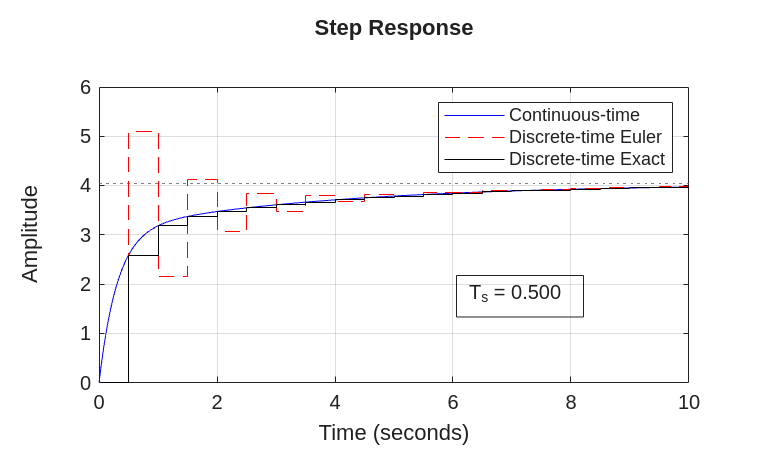


%% For the analysis of a step response, we add the columns of B
% Otherwise, we would analyse each input separately 
% Consult 'doc stepplot' for details
B = B(:,1)+B(:,2);
D = D(:,1)+D(:,2);

% Plot as in PS01 Ex. 2
close all
Ad_euler = eye(size(A))+T_s*A;
Bd_euler = T_s*B;
Cd = C;
Dd = D;

sys_cont  = ss(A,B,C,D);
sys_euler = ss(Ad_euler,Bd_euler,Cd,Dd,T_s);
sys_exact = c2d(sys_cont,T_s);


stepplot(sys_cont,'b',sys_euler,'r--',sys_exact,'k',10)
grid on
legend('Continuous-time','Discrete-time Euler','Discrete-time Exact')
str = sprintf('T_s = %1.3f',T_s);
annotation('textbox',[0.6 .1 .3 .3],'String',str,'FitBoxToText','on');


eigenvalues_euler = eig(sys_euler)

eigenvalues_euler =    -0.6154
    0.8654


eigenvalues_exact = eig(sys_exact)

eigenvalues_exact =     0.1988
    0.8740


T_s_batch = [1.0 0.5 0.1 0.05 0.01 0.001];


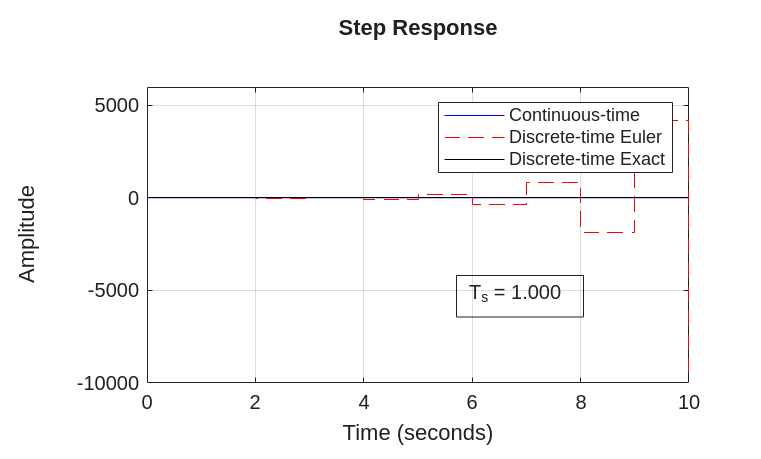


close all
T_s = T_s_batch(1);
Ad_euler = eye(size(A))+T_s*A;
Bd_euler = T_s*B;
Cd = C;
Dd = D;

sys_cont  = ss(A,B,C,D);
sys_euler = ss(Ad_euler,Bd_euler,Cd,Dd,T_s);
sys_exact = c2d(sys_cont,T_s);


stepplot(sys_cont,'b',sys_euler,'r--',sys_exact,'k',10)
grid on
legend('Continuous-time','Discrete-time Euler','Discrete-time Exact')
str = sprintf('T_s = %1.3f',T_s);
annotation('textbox',[0.6 .1 .3 .3],'String',str,'FitBoxToText','on');


eigenvalues_euler = eig(sys_euler)

eigenvalues_euler =    -2.2307
    0.7307


eigenvalues_exact = eig(sys_exact)

eigenvalues_exact =     0.0395
    0.7639



close all
T_s = T_s_batch(2);
Ad_euler = eye(size(A))+T_s*A;
Bd_euler = T_s*B;
Cd = C;
Dd = D;

sys_cont  = ss(A,B,C,D);
sys_euler = ss(Ad_euler,Bd_euler,Cd,Dd,T_s);
sys_exact = c2d(sys_cont,T_s);


stepplot(sys_cont,'b',sys_euler,'r--',sys_exact,'k',10)
grid on
legend('Continuous-time','Discrete-time Euler','Discrete-time Exact')
str = sprintf('T_s = %1.3f',T_s);
annotation('textbox',[0.6 .1 .3 .3],'String',str,'FitBoxToText','on');


eigenvalues_euler = eig(sys_euler)

eigenvalues_euler =    -0.6154
    0.8654


eigenvalues_exact = eig(sys_exact)

eigenvalues_exact =     0.1988
    0.8740


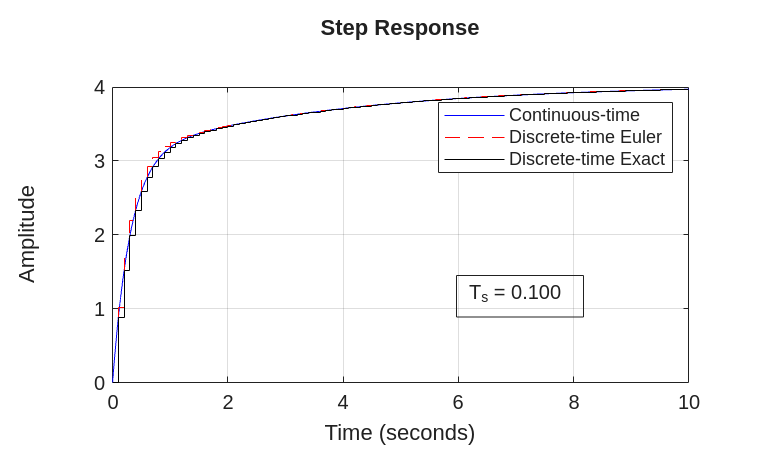


close all
T_s = T_s_batch(3);
Ad_euler = eye(size(A))+T_s*A;
Bd_euler = T_s*B;
Cd = C;
Dd = D;

sys_cont  = ss(A,B,C,D);
sys_euler = ss(Ad_euler,Bd_euler,Cd,Dd,T_s);
sys_exact = c2d(sys_cont,T_s);


stepplot(sys_cont,'b',sys_euler,'r--',sys_exact,'k',10)
grid on
legend('Continuous-time','Discrete-time Euler','Discrete-time Exact')
str = sprintf('T_s = %1.3f',T_s);
annotation('textbox',[0.6 .1 .3 .3],'String',str,'FitBoxToText','on');


eigenvalues_euler = eig(sys_euler)

eigenvalues_euler =     0.6769
    0.9731


eigenvalues_exact = eig(sys_exact)

eigenvalues_exact =     0.7239
    0.9734


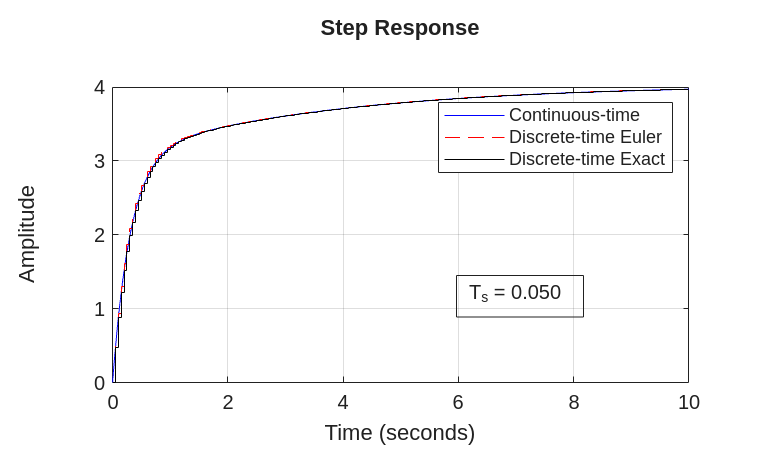


close all
T_s = T_s_batch(4);
Ad_euler = eye(size(A))+T_s*A;
Bd_euler = T_s*B;
Cd = C;
Dd = D;

sys_cont  = ss(A,B,C,D);
sys_euler = ss(Ad_euler,Bd_euler,Cd,Dd,T_s);
sys_exact = c2d(sys_cont,T_s);


stepplot(sys_cont,'b',sys_euler,'r--',sys_exact,'k',10)
grid on
legend('Continuous-time','Discrete-time Euler','Discrete-time Exact')
str = sprintf('T_s = %1.3f',T_s);
annotation('textbox',[0.6 .1 .3 .3],'String',str,'FitBoxToText','on');


eigenvalues_euler = eig(sys_euler)

eigenvalues_euler =     0.8385
    0.9865


eigenvalues_exact = eig(sys_exact)

eigenvalues_exact =     0.8508
    0.9866


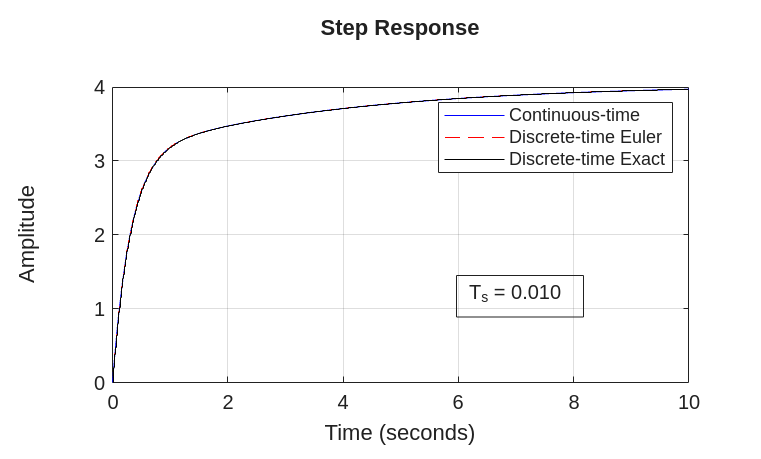


close all
T_s = T_s_batch(5);
Ad_euler = eye(size(A))+T_s*A;
Bd_euler = T_s*B;
Cd = C;
Dd = D;

sys_cont  = ss(A,B,C,D);
sys_euler = ss(Ad_euler,Bd_euler,Cd,Dd,T_s);
sys_exact = c2d(sys_cont,T_s);


stepplot(sys_cont,'b',sys_euler,'r--',sys_exact,'k',10)
grid on
legend('Continuous-time','Discrete-time Euler','Discrete-time Exact')
str = sprintf('T_s = %1.3f',T_s);
annotation('textbox',[0.6 .1 .3 .3],'String',str,'FitBoxToText','on');


eigenvalues_euler = eig(sys_euler)

eigenvalues_euler =     0.9677
    0.9973


eigenvalues_exact = eig(sys_exact)

eigenvalues_exact =     0.9682
    0.9973


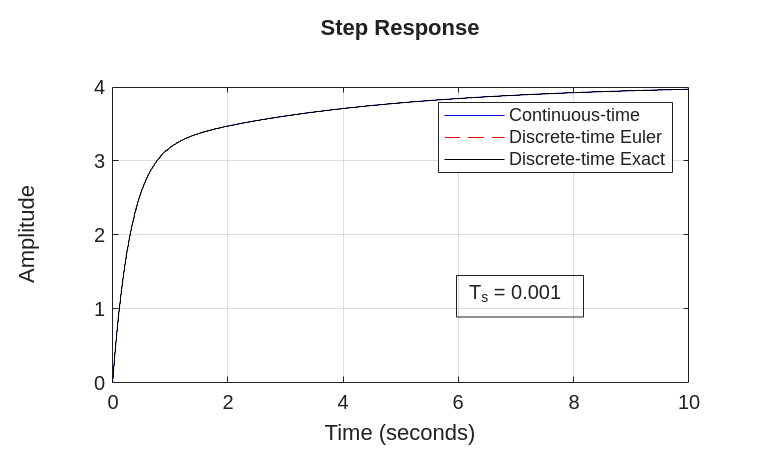


close all
T_s = T_s_batch(6);
Ad_euler = eye(size(A))+T_s*A;
Bd_euler = T_s*B;
Cd = C;
Dd = D;

sys_cont  = ss(A,B,C,D);
sys_euler = ss(Ad_euler,Bd_euler,Cd,Dd,T_s);
sys_exact = c2d(sys_cont,T_s);


stepplot(sys_cont,'b',sys_euler,'r--',sys_exact,'k',10)
grid on
legend('Continuous-time','Discrete-time Euler','Discrete-time Exact')
str = sprintf('T_s = %1.3f',T_s);
annotation('textbox',[0.6 .1 .3 .3],'String',str,'FitBoxToText','on');


eigenvalues_euler = eig(sys_euler)

eigenvalues_euler =     0.9968
    0.9997


eigenvalues_exact = eig(sys_exact)

eigenvalues_exact =     0.9968
    0.9997
